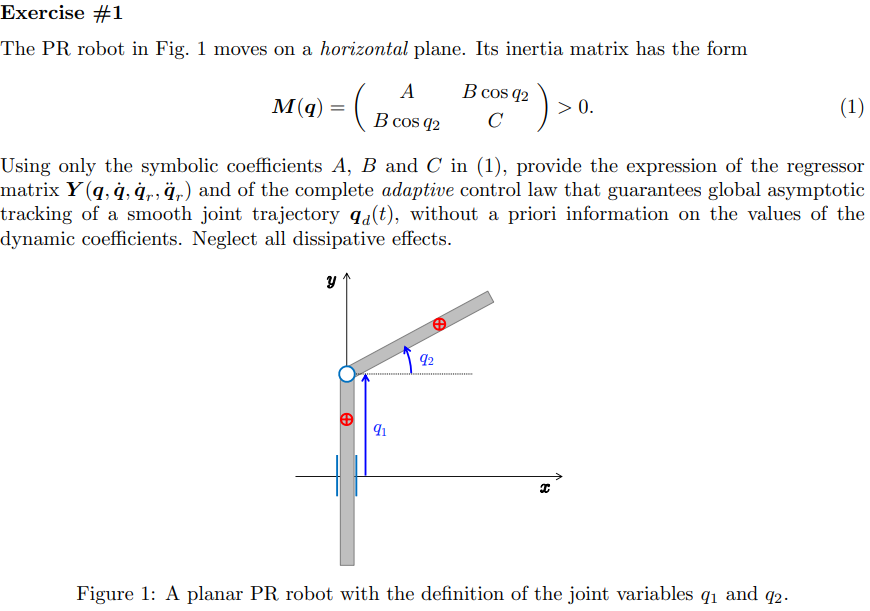

syms q1 q2 A B C q_dot_1r q_dot_2r q_ddot_1r q_ddot_2r real
syms L_1 L_2 L_3 L_4 q3 q4

M = [A B*cos(q2);
      B*cos(q2) C;];

% Coriolis and Centrifugal force
q  = [q1; q2;];
dqr = [q_dot_1r; q_dot_2r;];
dq = [q_dot_1; q_dot_2;];
ddq = [q_ddot_1r; q_ddot_2r;]; % Added acceleration terms
C_mat = sym(zeros(2,2)); % Renamed to avoid conflict with C parameter

for i = 1:2
    for j = 1:2
        tmp = 0;
        for k = 1:2
            tmp = tmp + 0.5 * ( ...
                diff(M(i,j), q(k)) + ...
                diff(M(i,k), q(j)) - ...
                diff(M(k,j), q(i)) ) * dq(k);
        end
        C_mat(i,j) = simplify(tmp);
    end
end

c_vec = simplify(C_mat * dqr)

$$c\_vec = \left(\begin{array}{c} -B\,{\dot{q}}_{2}\,{\dot{q}}_{\mathrm{2r}}\,\sin\left(q_{2}\right)\\ 0 \end{array}\right)$$


% Correct dynamic model: M*ddq + C*dq
dynamicModel = M * ddq + c_vec; % Now a 2x1 vector

params = [A B C];
Y = extract_Y_v3(dynamicModel, params)

$$Y = \left(\begin{array}{ccc} {\ddot{q}}_{\mathrm{1r}} & {\ddot{q}}_{\mathrm{2r}}\,\cos\left(q_{2}\right)-{\dot{q}}_{2}\,{\dot{q}}_{\mathrm{2r}}\,\sin\left(q_{2}\right) & 0\\ 0 & {\ddot{q}}_{\mathrm{1r}}\,\cos\left(q_{2}\right) & {\ddot{q}}_{\mathrm{2r}} \end{array}\right)$$


% Ensure the helper function is correctly handling vector inputs
function Y = extract_Y_v3(Ya, dynamic_symbols)
    Y = sym([]);
    Y_columns = length(dynamic_symbols);
    dynamic_symbols = reshape(dynamic_symbols, 1, Y_columns);

    for i=1:Y_columns
        subs_array = zeros(1, Y_columns);
        subs_array(i) = 1;
        Yi = subs(Ya, dynamic_symbols, subs_array);
        Y = [Y, Yi];
    end
end

#### 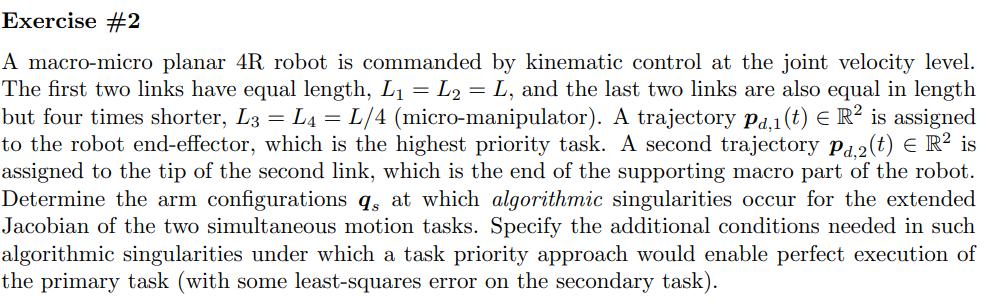

p_M = [L_1*cos(q1)+L_2*cos(q1+q2); L_1*sin(q1)+L_2*sin(q1+q2);]

$$p\_M = \left(\begin{array}{c} L_{2}\,\cos\left(q_{1}+q_{2}\right)+L_{1}\,\cos\left(q_{1}\right)\\ L_{2}\,\sin\left(q_{1}+q_{2}\right)+L_{1}\,\sin\left(q_{1}\right) \end{array}\right)$$

J_M = jacobian(p_M,[q1,q2,q3,q4])

$$J\_M = \left(\begin{array}{cccc} -L_{2}\,\sin\left(q_{1}+q_{2}\right)-L_{1}\,\sin\left(q_{1}\right) & -L_{2}\,\sin\left(q_{1}+q_{2}\right) & 0 & 0\\ L_{2}\,\cos\left(q_{1}+q_{2}\right)+L_{1}\,\cos\left(q_{1}\right) & L_{2}\,\cos\left(q_{1}+q_{2}\right) & 0 & 0 \end{array}\right)$$


p_m = [L_3*cos(q1+q2+q3)+L_4*cos(q1+q2+q3+q4); L_3*sin(q1+q2+q3)+L_4*sin(q1+q2+q3+q4);]

$$p\_m = \left(\begin{array}{c} L_{4}\,\cos\left(q_{1}+q_{2}+q_{3}+q_{4}\right)+L_{3}\,\cos\left(q_{1}+q_{2}+q_{3}\right)\\ L_{4}\,\sin\left(q_{1}+q_{2}+q_{3}+q_{4}\right)+L_{3}\,\sin\left(q_{1}+q_{2}+q_{3}\right) \end{array}\right)$$

J_m = jacobian(p_m,[q1,q2,q3,q4])

$$J\_m = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{1} & \sigma_{1} & \sigma_{1} & -L_{4}\,\sin\left(q_{1}+q_{2}+q_{3}+q_{4}\right)\\ \sigma_{2} & \sigma_{2} & \sigma_{2} & L_{4}\,\cos\left(q_{1}+q_{2}+q_{3}+q_{4}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-L_{4}\,\sin\left(q_{1}+q_{2}+q_{3}+q_{4}\right)-L_{3}\,\sin\left(q_{1}+q_{2}+q_{3}\right)\\ \sigma_{2}=L_{4}\,\cos\left(q_{1}+q_{2}+q_{3}+q_{4}\right)+L_{3}\,\cos\left(q_{1}+q_{2}+q_{3}\right) \end{array}$$


J_e = [J_M; J_m];
det_J_e = simplify(det(J_e))

$$det\_J\_e = L_{1}\,L_{2}\,L_{3}\,L_{4}\,\sin\left(q_{2}\right)\,\sin\left(q_{4}\right)$$